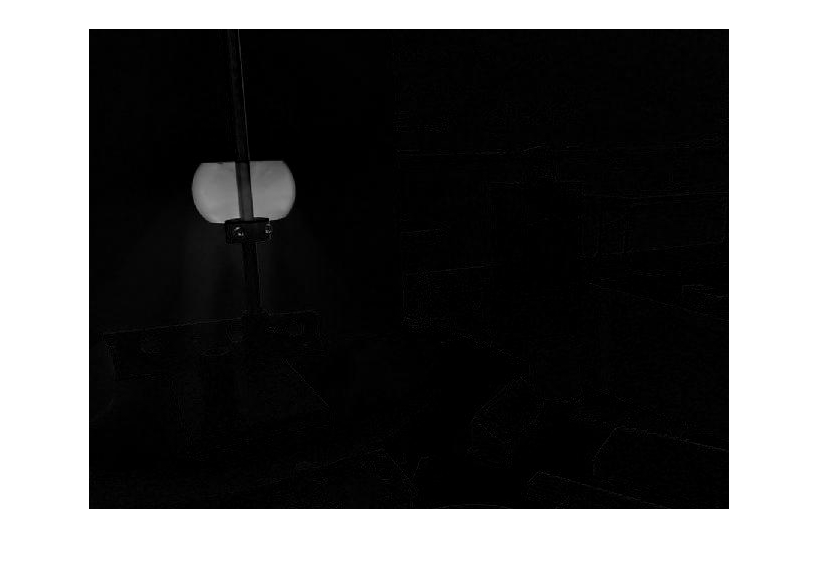

% import images to compare
img1 = imread("background.jpg");
img2 = imread("target.jpg");
% convert to grayscale
imgray1 = rgb2gray(img1);
imgray2 = rgb2gray(img2);
% subtract images
imdiff = abs(imgray1 - imgray2);
figure 
imshow(imdiff)

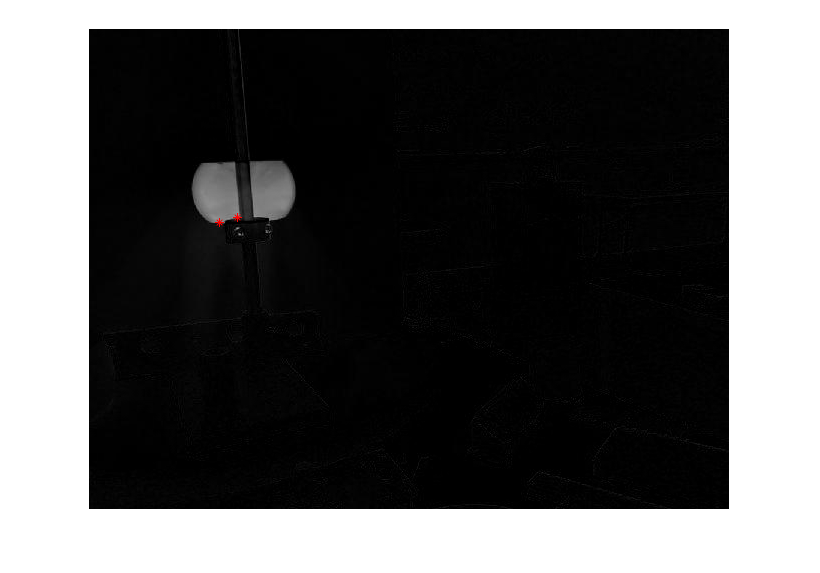

% finding max location of difference
maxdiff = max(max(imdiff));
[irow, icol] = find(imdiff == maxdiff);
[m,n] = size(imdiff);
%plotting it in red
imshow(imdiff)
hold on
plot(icol, irow,'r*')
hold off

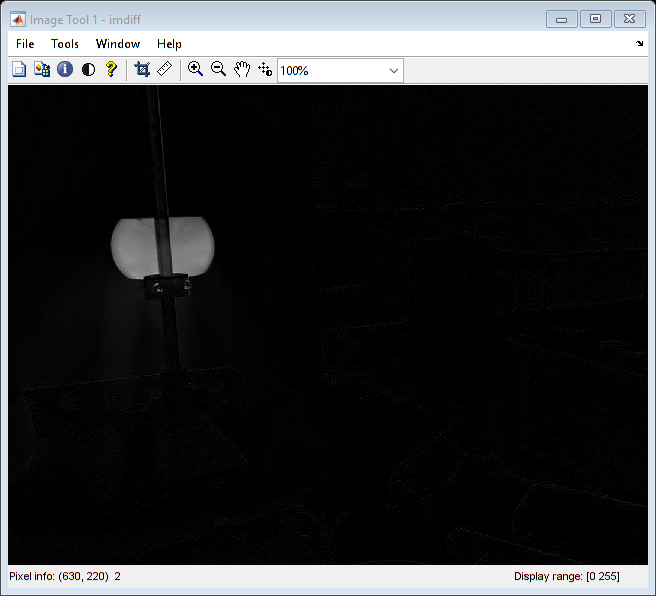

imtool(imdiff)

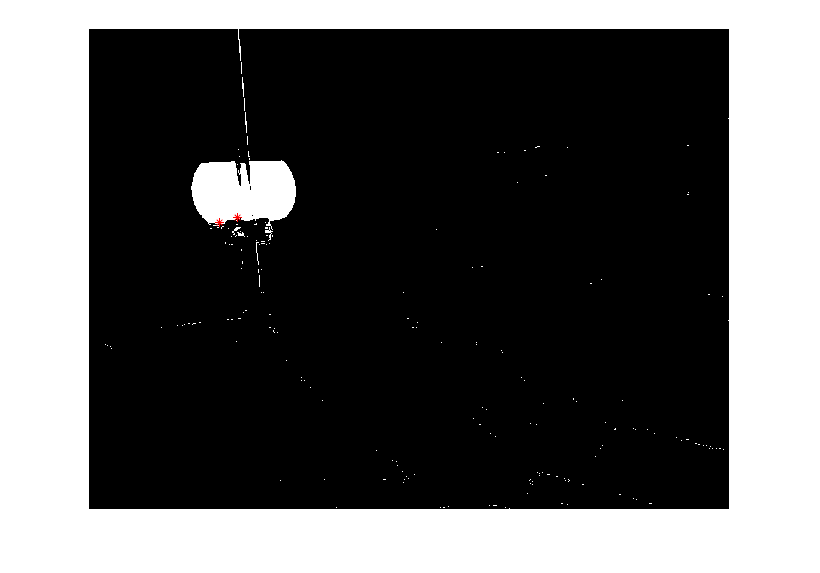

% threshold image
image_threshold = imdiff > 20;
figure
imshow(image_threshold)
hold on
plot(icol,irow,'r*')
hold off

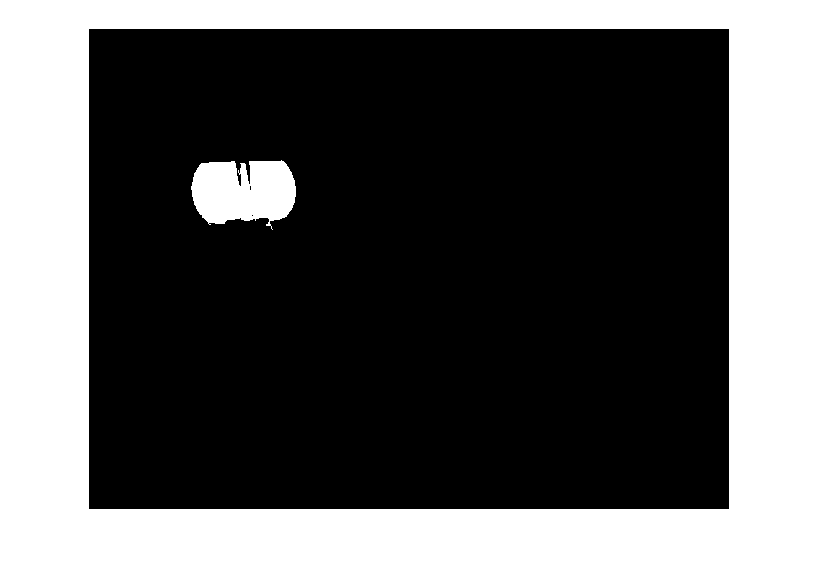

% clean up threshold image
imgfilled = bwareaopen(image_threshold,100);
figure 
imshow(imgfilled)

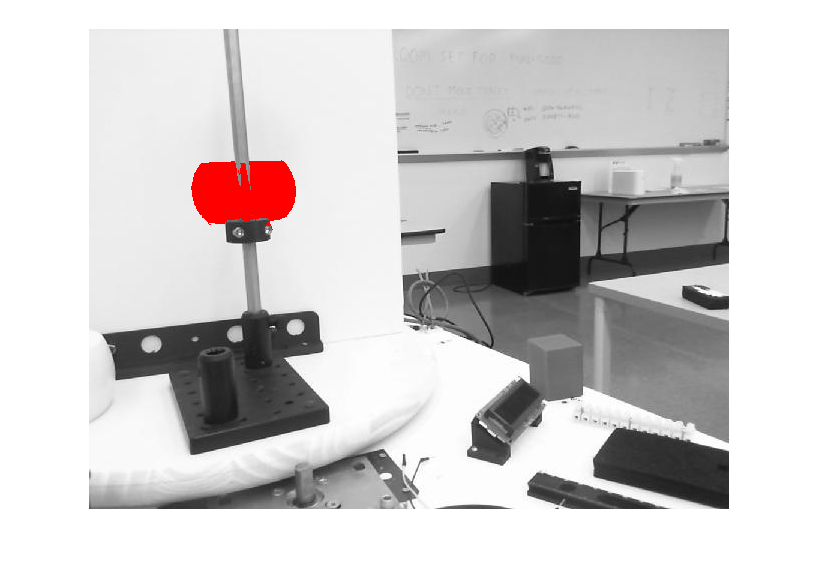

% overlay onto original image
%download image overlay
image_both = imoverlay(imgray1,imgfilled,[1 0 0]);

figure
imshow(image_both)